# Data processing and visualization

In this chapter we will take a look at some useful methods for processing data as well as visualization and things like saving data.

**New**: Smoothing of data; Sometimes our data is really noisy. To reduce the noise we can use smooth()

data = readtable('sinNoisy.csv');
data = table2array(data);

plot(data(:,1), data(:,2), '.')
hold on

**Exercise:** Try to use the smooth()-function (google the function), to smooth the y-data. Try different smoothing windows/spans and plot the smoothed data to compare it with the original.

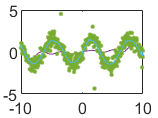

% your code
smoothed = smooth(data(:,2), 30);
plot(data(:,1), smoothed)
pause(1)

**New:** Sometimes we need to delete some specific outliers, which may interrupt our analysis. There for we will take a look at following data:

% together
data = readtable('sinNoisy.csv');
data = table2array(data);

**Exercsie:** Think of a way getting rid of those outliers.

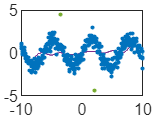

% your code
data(242,:) = [];
data(132,:) = [];
plot(data(:,1), data(:,2), '.');

**New:** To safe our processed data to a file we can use **writematrix(**values, filname**)**, where "values are the matrix we want to safe to a .csv file.

**Example:**

% together
writematrix(smoothed, 'smoothed.csv')

**Exercise**: Safe the corrected data of the exercise into a .csv file.

% your code
writematrix(data, 'corrected.csv')

**Exercise: **

- Look at the raw file of wages

- Import the sheet wages. 

- Plot a nice bar-diagram (Google!) to visualize the data to get an overview

- Now try to order the wages in an ascending order (**Hint**: Google for sort()-function). You will notice that you are just able to sort by numeric data types. Since you also want to order the jobs, you also need to get the sorting index ( [data, index] = sort() ). Therefor you will find good examples on the Mathworks-Website.

- You will notice that the bar()-function orders alphabetically. To compensate this problem we need to turn the data into categorial data type **categorical**(). Do it!

- In the end, find the three highest paid jobs as well as the three lowest paid jobs (**Hint: **use "end" do access the right indices). Export those to an extra data file (**Hint: **Pay attention to the right data type).

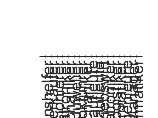

data = readtable('wages.txt');
wages = table2array(data(:,2));
jobsList = string(table2array(data(:,1)));

[sorted, indexSorted] = sort(wages);
jobs = categorical(jobsList(indexSorted));

figure
bar(sorted)
set(gca, 'XTick', 1:length(sorted))
xticklabels(categorical(jobs))

sorted = string(sorted);
jobs = string(jobs);
paid = [jobs(end-2:end), sorted(end-2:end); jobs(1:3), sorted(1:3)]

paid = 6×2 string array
    "Ingenieure"                  "3850"
    "Key Account Manager"         "3900"
    "Wirtschafts-Informatiker"    "4350"
    "Produktionshelfer"           "1600"
    "Verkäufer"                   "1600"
    "Kommissionierer"             "1700"


writematrix(paid, 'paidJobs.csv')